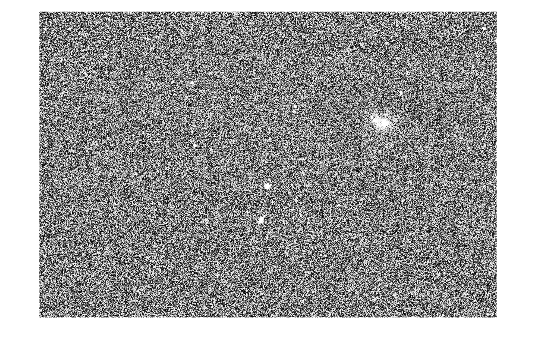

clc ; clear all ; close all ;
img = imread("D:\IMAGES\ORION\pipp_20240331_003120\_MG_0082\_MG_0047.tif"); % Replace with your image file

% Convert the image to grayscale if it is in RGB
if size(img, 3) == 3
    img_gray = rgb2gray(img);
else
    img_gray = img;
end

clahe_img = adapthisteq(img_gray, 'ClipLimit', 1,'NumTiles',[8 8]);
clahe_img1 = adapthisteq(clahe_img, 'ClipLimit', 1,'NumTiles',[8 8]);
imshow(clahe_img1);

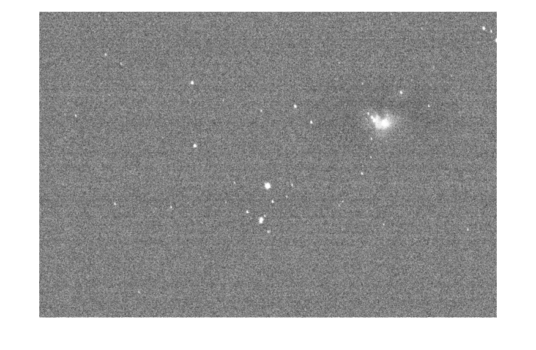

filteredImage = imgaussfilt(clahe_img1, 6); 
imshow(filteredImage);

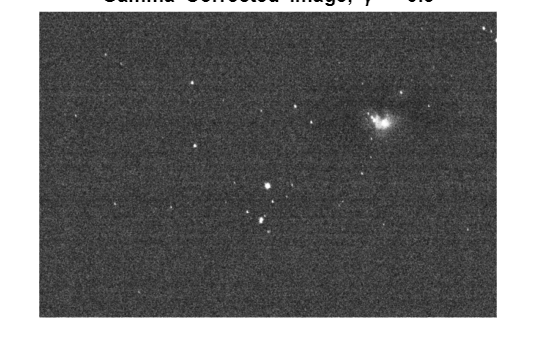

image_double = im2double(filteredImage);
gamma = 0.5;

% Apply gamma correction to each channel (R, G, B)
corrected_image = image_double .^ (1/gamma);

% Display the gamma-corrected image
figure;
imshow(corrected_image);
title(['Gamma Corrected Image, \gamma = ', num2str(gamma)]);

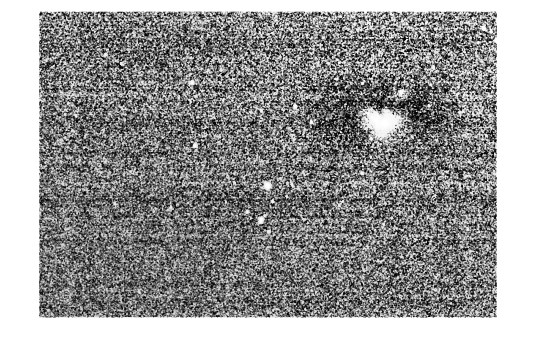

clahe_img2 = adapthisteq(corrected_image, 'ClipLimit', 0.01,'NumTiles',[2 2]);
clahe_img3 = adapthisteq(clahe_img2, 'ClipLimit', 0.01,'NumTiles',[2 2]);
imshow(clahe_img3);

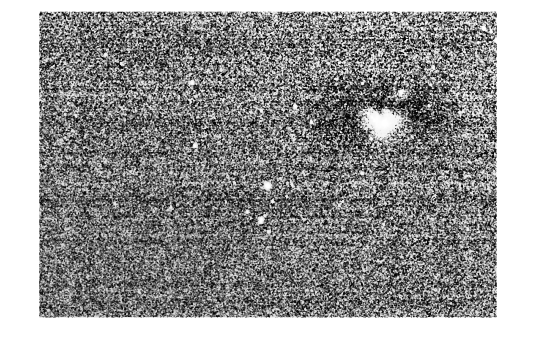

filteredImage2 = medfilt2(clahe_img3);
imshow(filteredImage2);

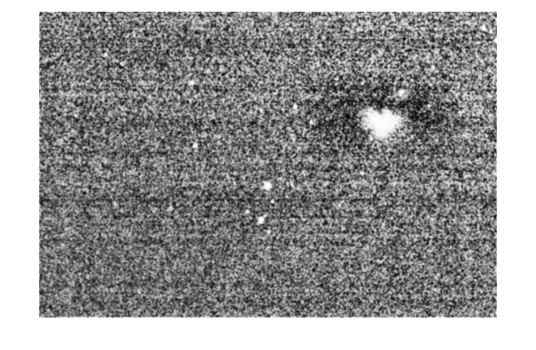

filteredImage4 = imgaussfilt(filteredImage2,8);
imshow(filteredImage4);

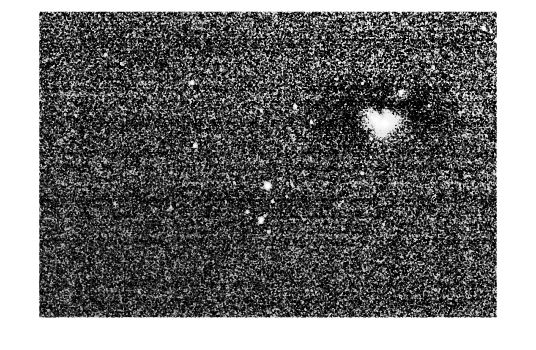

image_double = im2double(filteredImage2);
gamma = 0.5;

% Apply gamma correction to each channel (R, G, B)
corrected_image = image_double .^ (1/gamma);

% Display the gamma-corrected image
figure;
imshow(corrected_image);

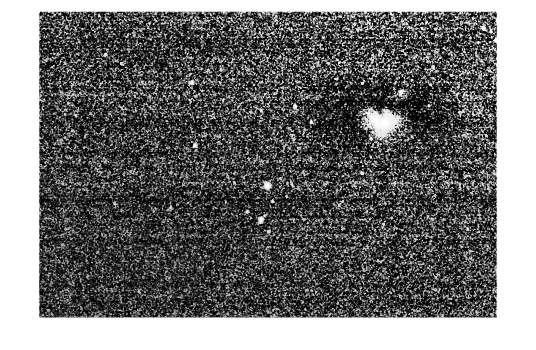

filteredImage3 = medfilt2(corrected_image,[2,2]);
imshow(filteredImage3);

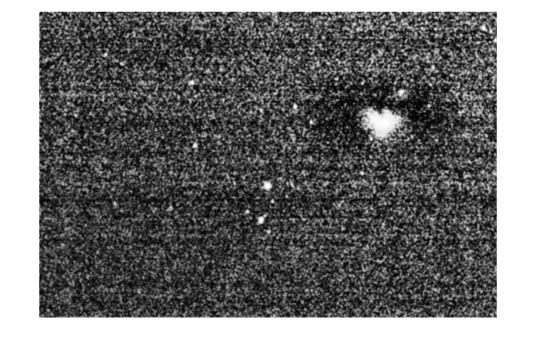

filteredImage5 = imgaussfilt(filteredImage3,8);
imshow(filteredImage5);

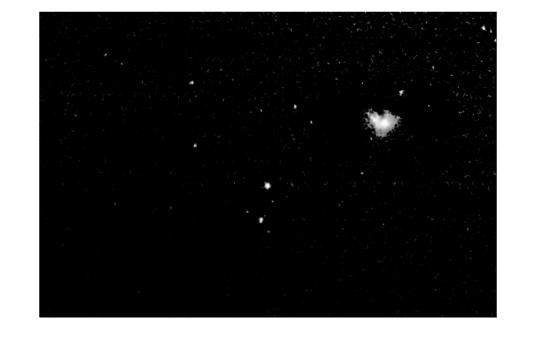

image_double = im2double(filteredImage5);
gamma = 0.15;

% Apply gamma correction to each channel (R, G, B)
corrected_image = image_double .^ (1/gamma);

% Display the gamma-corrected image
figure;
imshow(corrected_image);

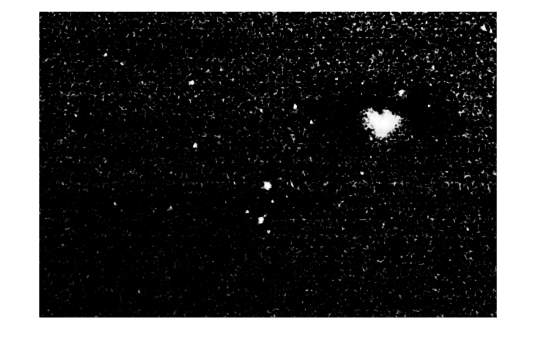

new_img = imlocalbrighten(corrected_image);
imshow(new_img);